%1
T = import_airborne_gravity_data('Data/Q1/RESOURCES/NGS_GRAVD_Block_CN03_BETA1/NGS_GRAVD_Block_CN03_Gravity_Data_BETA1.txt')

T = 	1.0e+05 *

    0.0004   -0.0010    9.7849    0.0636
    0.0004   -0.0010    9.7849    0.0636
    0.0004   -0.0010    9.7849    0.0636
    0.0004   -0.0010    9.7849    0.0637
    0.0004   -0.0010    9.7849    0.0637
    0.0004   -0.0010    9.7849    0.0637
    0.0004   -0.0010    9.7849    0.0637
    0.0004   -0.0010    9.7849    0.0637
    0.0004   -0.0010    9.7849    0.0637
    0.0004   -0.0010    9.7849    0.0637



latitude = T(:,1);
longitude = T(:,2);
elipsoidal_height = T(:,3);
gravity_filtered = T(:,4);
Ellipsoid = make_Ellipsoid('WGS84')

Ellipsoid = struct with fields:
              GM: 3.9860e+14
           omega: 7.2921e-05
    gammaEquator: 9.7803e+05
       gammaPole: 9.8322e+05
               a: 6378137
               b: 6.3568e+06
               e: 0.0818
              e2: 0.0067
               f: 0.0034


%2 
%N_ggm = open('/Users/sunilbhavsar/Documents/CE678_PROJECT/Q2/RESOURCES/AIUB-CHAMP01S_a50de3dfc2ab0cdb9a2ae28b113f3398304202075281a813ba9cc27562a667af.gdf')
%a = open('/Users/sunilbhavsar/Documents/CE678_PROJECT/AIUB-CHAMP01S_a50de3dfc2ab0cdb9a2ae28b113f3398304202075281a813ba9cc27562a667af.gdf')
fid = fopen('Data/Q2/Downloaded_data/GGM02C.gdf'); % file identifier

h = true; % while loop condition

n = 1; % headerlines counter

while true

    str = fgets(fid); % reading the file line by line
    
    if length(str) >= 11
        indx = strcmp(str(1:11), 'end_of_head'); % checking for 'end_of_head' string
    else
        indx = false;
    end
    
    if indx == 0
    
    n = n+1; % keep counting
    
    else
    
    h = false; % break loop
    break;
    
    end

end
str = fgets(fid);
fclose(fid);
GGM01C = textread('Data/Q2/Downloaded_data/GGM02C.gdf','', 'headerlines', n);
GGM01C_longitudes = GGM01C(:,1)-360;
GGM01C_latitudes = GGM01C(:,2);
GGM01C_geoid = GGM01C(:,3);

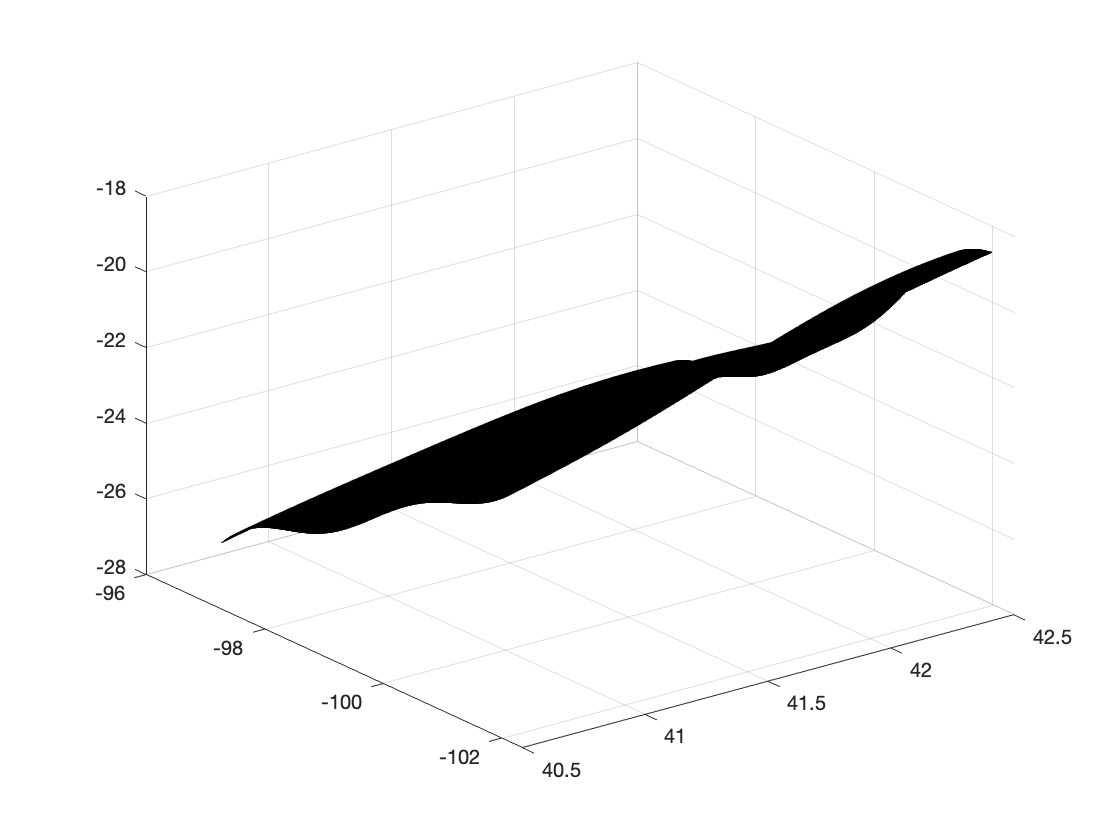

%adding 
n_ggm = griddata(GGM01C_latitudes,GGM01C_longitudes,GGM01C_geoid,Latitude_grid,Longitude_grid,"nearest");
surf(Latitude_grid,Longitude_grid,n_ggm)

orthometric_height = n_ggm+elipsoidal_height;

%3
Ellipsoid = make_Ellipsoid('WGS84');
free_air_anomily = gravity_filtered - calc_FAC(Latitude_grid,Ellipsoid,orthometric_height)-calc_gnorm_ellip_surface(Latitude_grid,Ellipsoid);


%4
fid = fopen('Data/Q4/GGM02C_Anomily.gdf'); % file identifier

h = true; % while loop condition

n = 1; % headerlines counter

while true

    str = fgets(fid); % reading the file line by line
    
    if length(str) >= 11
        indx = strcmp(str(1:11), 'end_of_head'); % checking for 'end_of_head' string
    else
        indx = false;
    end
    
    if indx == 0
    
    n = n+1; % keep counting
    
    else
    
    h = false; % break loop
    break;
    
    end

end
str = fgets(fid);
fclose(fid);
GGM01C_anomily = textread('Data/Q4/GGM02C_Anomily.gdf','', 'headerlines', n);
GGM01C_anomily_longitude = GGM01C_anomily(:,1)-360;
GGM01C_anomily_latitude = GGM01C_anomily(:,2);
GGM01C_anomily_gravity_anomily = GGM01C_anomily(:,4);

del_g_ggm = griddata(GGM01C_anomily_latitude,GGM01C_anomily_longitude,GGM01C_anomily_gravity_anomily,Latitude_grid,Longitude_grid);
del_g_s_and_mw = free_air_anomily-del_g_ggm;

%5,6
g_atm = 0.871 - 1.0298*(10^(-4))*orthometric_height + 5.3105*(10^-9)*(orthometric_height.^2)  - 2.1642*(10^-13)*(orthometric_height.^3)+ 9.5246*(10^-18)*(orthometric_height.^4) - 2.2411*(10^-22)*(orthometric_height.^5);
g_atm_and_s_mw = del_g_s_and_mw - g_atm;

%7
files = ['Data/Q7/srtm_16_04/srtm_16_04.asc';'Q7/srtm_17_04/srtm_17_04.asc'];
H = combine_DEM_data(files,Latitude_grid,Longitude_grid);

tc = terrain_correction(H,Latitude_grid,Longitude_grid,0.01);

Determining spatial grids
Setting up integration kernel
FFT kernel for TC
FFT H^2
FFT H
FFT ones
Computing TC


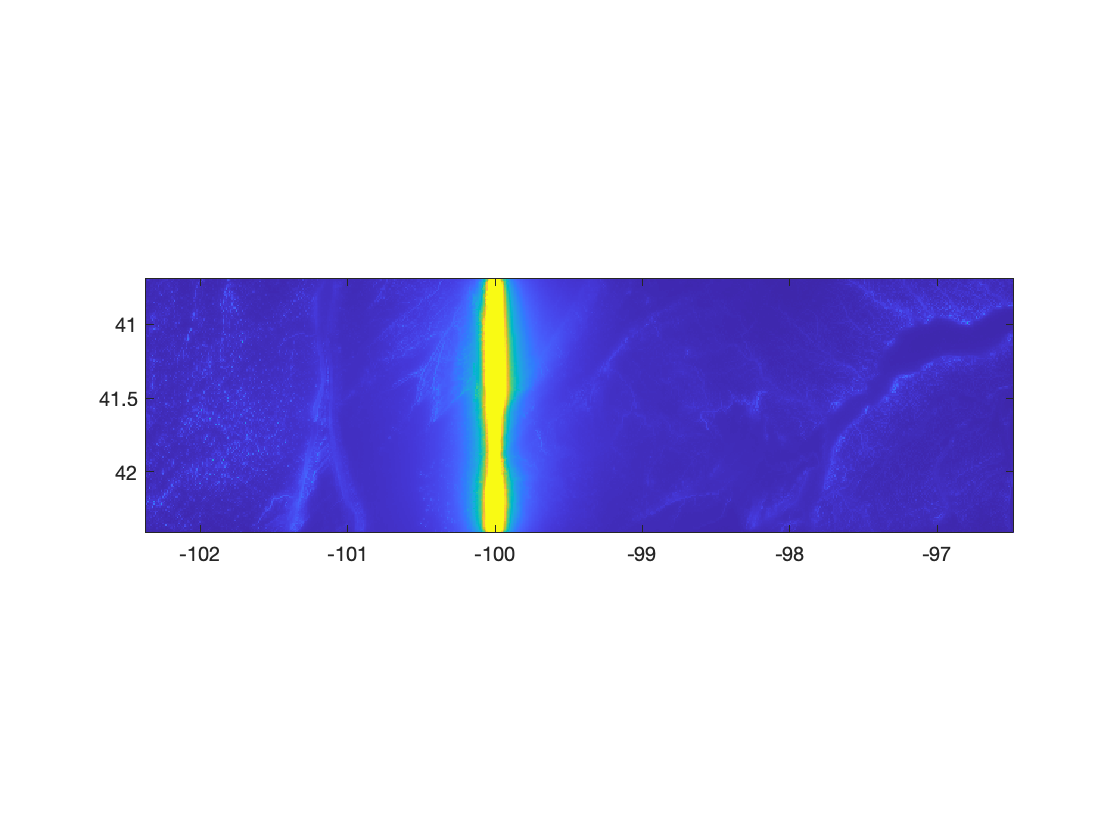

imagesc(long,lat,tc)
axis image
caxis([0 1])

gfaye = g_atm_and_s_mw-tc

gfaye =   -13.6590  -13.4919  -13.1180  -12.5441  -12.9823  -13.0727  -12.5297  -12.5761  -12.6639  -12.6300  -12.3464  -12.1583  -11.6937  -11.3692  -11.5730  -12.1430  -12.0003  -11.7436  -12.0410  -11.9918  -12.0681  -12.4732  -12.3873  -12.2792  -12.6500  -12.6955  -12.4788  -12.6254  -12.5323  -12.7482  -12.9290  -13.0831  -13.0299  -12.7754  -12.7082  -12.4109  -12.1542  -12.1726  -12.2896  -12.0590  -11.9473  -12.0666  -11.5911  -11.3190  -11.3366  -11.6472  -11.4985  -11.2457  -10.4594  -10.0865
  -13.4503  -13.3586  -12.9464  -12.3632  -12.7700  -12.8076  -12.2991  -12.3837  -12.4767  -12.3905  -12.0585  -11.8662  -11.4602  -11.1468  -11.3403  -11.7757  -11.5917  -11.4171  -11.7622  -11.6673  -11.8039  -12.2528  -12.1294  -11.9249  -12.3072  -12.3948  -12.1651  -12.3267  -12.4069  -12.6447  -12.7907  -12.9054  -12.8578  -12.5637  -12.4376  -12.1377  -11.9149  -11.9343  -12.1116  -11.9328  -11.8651  -11.9658  -11.4964  -11.1881  -11.1414  -11.3487  -11.1493  -10.9481  -10.2713 

max(Longitude_grid(:))

ans = -96.4837

%8
%and 9

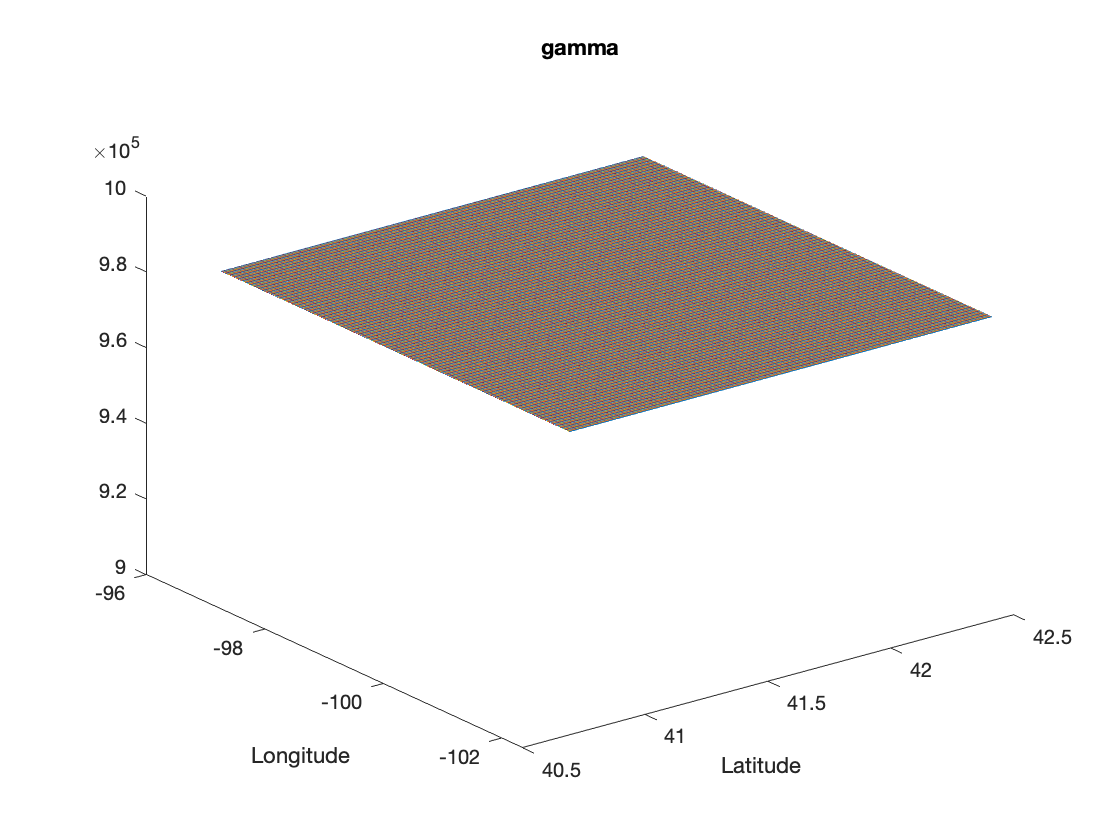

Tr = calc_disturb_potential(H,Latitude_grid,Longitude_grid,gfaye);

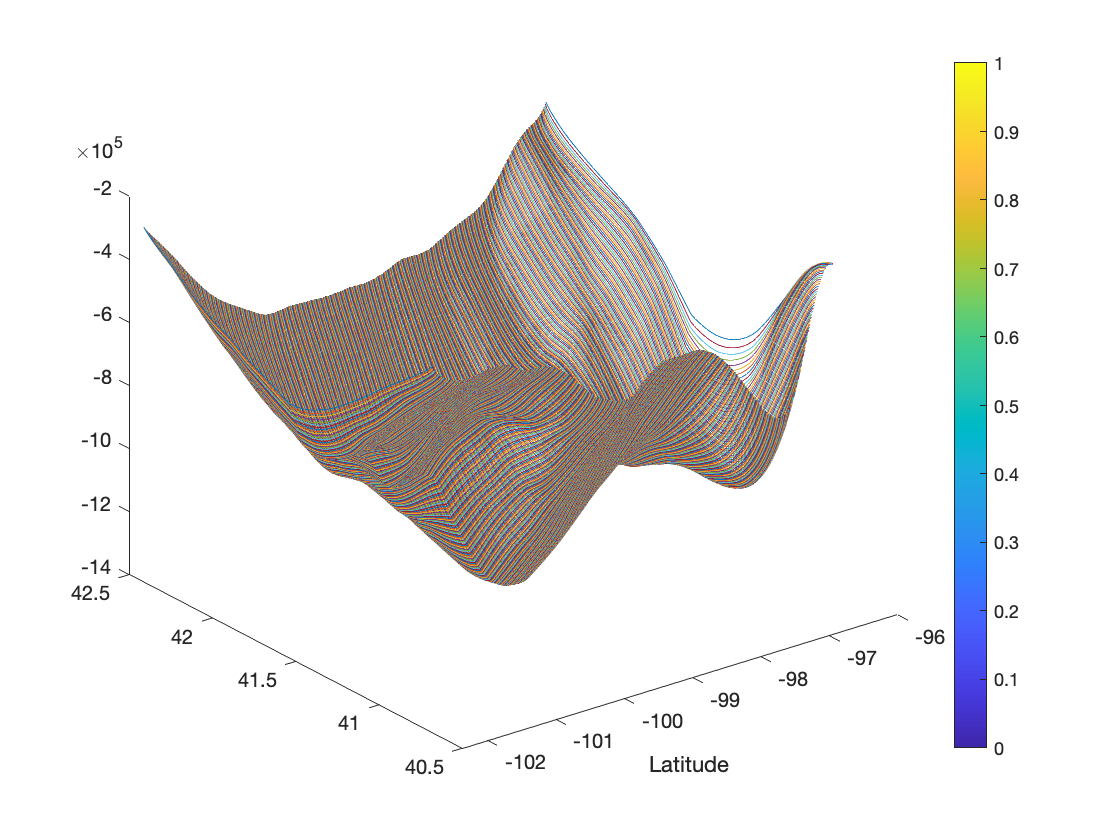

cx = 87

cy = 295

ans = 4.6957e+04

stokes = 	1.0e+04 *

    0.0045    0.0045    0.0045    0.0045    0.0045    0.0046    0.0046    0.0046    0.0046    0.0046    0.0046    0.0047    0.0047    0.0047    0.0047    0.0047    0.0047    0.0047    0.0048    0.0048    0.0048    0.0048    0.0048    0.0048    0.0049    0.0049    0.0049    0.0049    0.0049    0.0049    0.0050    0.0050    0.0050    0.0050    0.0050    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0052    0.0052    0.0052    0.0052    0.0052    0.0053    0.0053    0.0053    0.0053
    0.0045    0.0045    0.0045    0.0045    0.0046    0.0046    0.0046    0.0046    0.0046    0.0046    0.0046    0.0047    0.0047    0.0047    0.0047    0.0047    0.0047    0.0048    0.0048    0.0048    0.0048    0.0048    0.0048    0.0049    0.0049    0.0049    0.0049    0.0049    0.0049    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0051    0.0051    0.0051    0.0051    0.0051    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0053    0.00

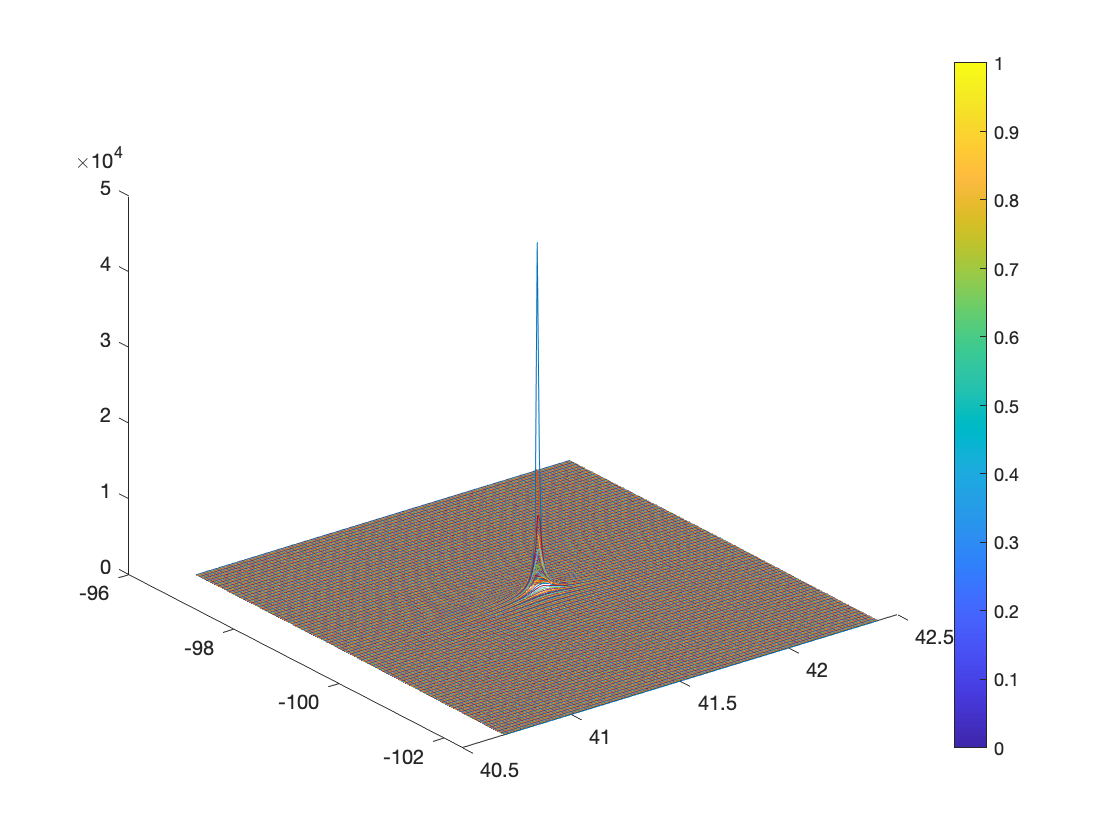

Tr_term1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0  

Tr_term2 = 	1.0e+04 *

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

ans = -1.2214

ans = 14.9919

Tr = 	1.0e+08 *

   -0.3037   -0.3091   -0.3136   -0.3179   -0.3218   -0.3252   -0.3285   -0.3317   -0.3346   -0.3373   -0.3398   -0.3422   -0.3446   -0.3471   -0.3497   -0.3520   -0.3543   -0.3567   -0.3589   -0.3612   -0.3635   -0.3655   -0.3675   -0.3695   -0.3714   -0.3731   -0.3748   -0.3765   -0.3782   -0.3797   -0.3811   -0.3824   -0.3834   -0.3843   -0.3851   -0.3859   -0.3867   -0.3876   -0.3883   -0.3889   -0.3895   -0.3898   -0.3901   -0.3905   -0.3909   -0.3912   -0.3913   -0.3912   -0.3911   -0.3912
   -0.3126   -0.3185   -0.3234   -0.3280   -0.3321   -0.3357   -0.3392   -0.3425   -0.3455   -0.3482   -0.3508   -0.3533   -0.3557   -0.3582   -0.3609   -0.3633   -0.3657   -0.3681   -0.3705   -0.3728   -0.3752   -0.3773   -0.3793   -0.3814   -0.3833   -0.3851   -0.3870   -0.3888   -0.3905   -0.3921   -0.3936   -0.3948   -0.3958   -0.3967   -0.3975   -0.3983   -0.3991   -0.3999   -0.4007   -0.4013   -0.4019   -0.4022   -0.4024   -0.4026   -0.4030   -0.4031   -0.4032   -0.4031  

Nr = 	1.0e+06 *

   -0.2462   -0.2504   -0.2540   -0.2575   -0.2606   -0.2633   -0.2660   -0.2685   -0.2709   -0.2730   -0.2750   -0.2769   -0.2788   -0.2809   -0.2829   -0.2848   -0.2867   -0.2886   -0.2904   -0.2922   -0.2940   -0.2957   -0.2972   -0.2988   -0.3003   -0.3017   -0.3031   -0.3045   -0.3058   -0.3070   -0.3082   -0.3091   -0.3099   -0.3106   -0.3112   -0.3118   -0.3125   -0.3131   -0.3137   -0.3142   -0.3146   -0.3148   -0.3150   -0.3153   -0.3156   -0.3157   -0.3158   -0.3157   -0.3157   -0.3158
   -0.2530   -0.2576   -0.2614   -0.2651   -0.2683   -0.2712   -0.2740   -0.2767   -0.2791   -0.2812   -0.2833   -0.2853   -0.2872   -0.2893   -0.2914   -0.2933   -0.2953   -0.2972   -0.2991   -0.3010   -0.3029   -0.3046   -0.3062   -0.3078   -0.3094   -0.3108   -0.3123   -0.3138   -0.3152   -0.3164   -0.3176   -0.3185   -0.3193   -0.3200   -0.3206   -0.3212   -0.3219   -0.3225   -0.3231   -0.3236   -0.3240   -0.3242   -0.3244   -0.3246   -0.3248   -0.3249   -0.3249   -0.3248  

Nr = calc_undulation(Tr,Latitude_grid,Ellipsoid);


max_lat = 42.4108

min_lat = 40.6908

max_lon = -96.4837

min_lon = -102.3637

lat_center = 41.5508

lon_center = -99.4237

si =     2.3757    2.3687    2.3617    2.3547    2.3477    2.3407    2.3337    2.3267    2.3197    2.3127    2.3057    2.2987    2.2917    2.2847    2.2777    2.2708    2.2638    2.2568    2.2499    2.2429    2.2360    2.2290    2.2221    2.2151    2.2082    2.2012    2.1943    2.1874    2.1805    2.1735    2.1666    2.1597    2.1528    2.1459    2.1390    2.1321    2.1252    2.1183    2.1115    2.1046    2.0977    2.0908    2.0840    2.0771    2.0703    2.0634    2.0566    2.0497    2.0429    2.0361
    2.3720    2.3649    2.3579    2.3509    2.3439    2.3368    2.3298    2.3228    2.3158    2.3088    2.3018    2.2948    2.2878    2.2808    2.2738    2.2669    2.2599    2.2529    2.2459    2.2390    2.2320    2.2250    2.2181    2.2111    2.2042    2.1972    2.1903    2.1833    2.1764    2.1695    2.1625    2.1556    2.1487    2.1418    2.1349    2.1280    2.1211    2.1142    2.1073    2.1004    2.0935    2.0866    2.0797    2.0729    2.0660    2.0591    2.0523    2.0454    2.0386    

Tr_stokes_fft = 	1.0e+07 *

   1.3743 + 0.0000i   1.2514 + 0.0044i   0.9471 + 0.0067i   0.6107 + 0.0065i   0.3795 + 0.0054i   0.2986 + 0.0053i   0.3143 + 0.0067i   0.3341 + 0.0083i   0.3018 + 0.0086i   0.2283 + 0.0073i   0.1640 + 0.0058i   0.1454 + 0.0057i   0.1650 + 0.0070i   0.1843 + 0.0085i   0.1736 + 0.0086i   0.1365 + 0.0073i   0.1021 + 0.0058i   0.0944 + 0.0057i   0.1106 + 0.0071i   0.1263 + 0.0085i   0.1211 + 0.0086i   0.0969 + 0.0072i   0.0738 + 0.0058i   0.0697 + 0.0057i   0.0829 + 0.0071i   0.0959 + 0.0085i   0.0928 + 0.0086i   0.0749 + 0.0072i   0.0577 + 0.0058i   0.0551 + 0.0057i   0.0663 + 0.0071i   0.0772 + 0.0085i   0.0752 + 0.0086i   0.0610 + 0.0072i   0.0473 + 0.0057i   0.0455 + 0.0057i   0.0551 + 0.0071i   0.0644 + 0.0085i   0.0630 + 0.0086i   0.0513 + 0.0072i   0.0400 + 0.0057i   0.0387 + 0.0057i   0.0470 + 0.0071i   0.0553 + 0.0085i   0.0542 + 0.0085i   0.0443 + 0.0071i   0.0346 + 0.0057i   0.0336 + 0.0057i   0.0410 + 0.0071i   0.0483 + 0.0085i
   1.1962 + 0.0133i  

Tr_g_fft = 	1.0e+06 *

  -1.1201 + 0.0000i   0.9297 - 0.0688i  -0.4748 + 0.1053i   0.0216 - 0.0925i   0.1991 + 0.0385i  -0.1393 + 0.0262i  -0.0626 - 0.0640i   0.2097 + 0.0518i  -0.1959 + 0.0033i   0.0636 - 0.0666i   0.0614 + 0.0973i  -0.0866 - 0.0756i   0.0202 + 0.0159i   0.0554 + 0.0439i  -0.0680 - 0.0691i   0.0155 + 0.0521i   0.0443 - 0.0145i  -0.0559 - 0.0124i   0.0161 + 0.0123i   0.0297 + 0.0058i  -0.0358 - 0.0191i  -0.0017 + 0.0121i   0.0454 + 0.0103i  -0.0558 - 0.0288i   0.0268 + 0.0273i   0.0124 - 0.0070i  -0.0289 - 0.0159i   0.0163 + 0.0246i   0.0035 - 0.0151i  -0.0058 - 0.0022i  -0.0121 + 0.0131i   0.0302 - 0.0117i  -0.0283 + 0.0033i   0.0070 + 0.0025i   0.0132 - 0.0016i  -0.0136 - 0.0023i  -0.0044 + 0.0028i   0.0208 + 0.0018i  -0.0173 - 0.0071i  -0.0045 + 0.0076i   0.0251 - 0.0024i  -0.0262 - 0.0035i   0.0082 + 0.0048i   0.0112 - 0.0006i  -0.0146 - 0.0043i   0.0013 + 0.0047i   0.0134 - 0.0000i  -0.0144 - 0.0053i   0.0012 + 0.0063i   0.0122 - 0.0023i
   0.9376 - 0.0537i  -0.82

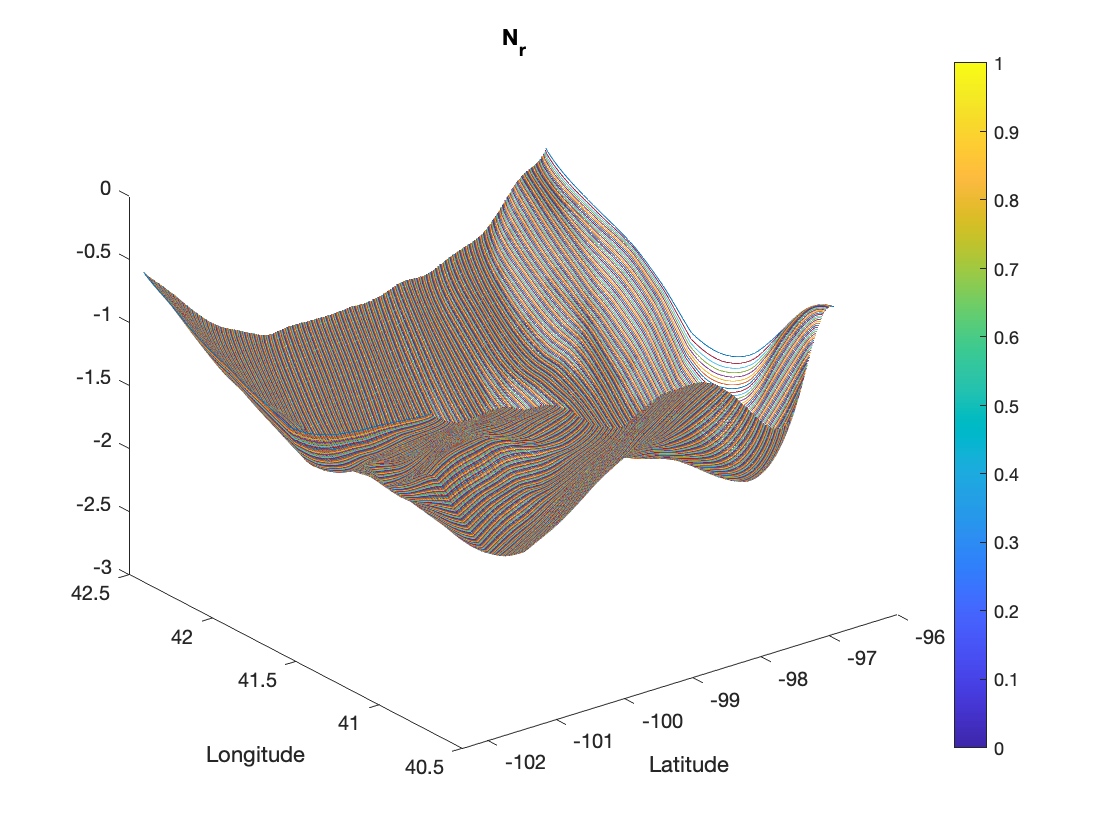

%10
N_co_geoid = calc_n_cogeoid(Nr,n_ggm,Latitude_grid,Longitude_grid,Latitude_grid,Longitude_grid);

meshz(Latitude_grid,Longitude_grid,N_co_geoid)


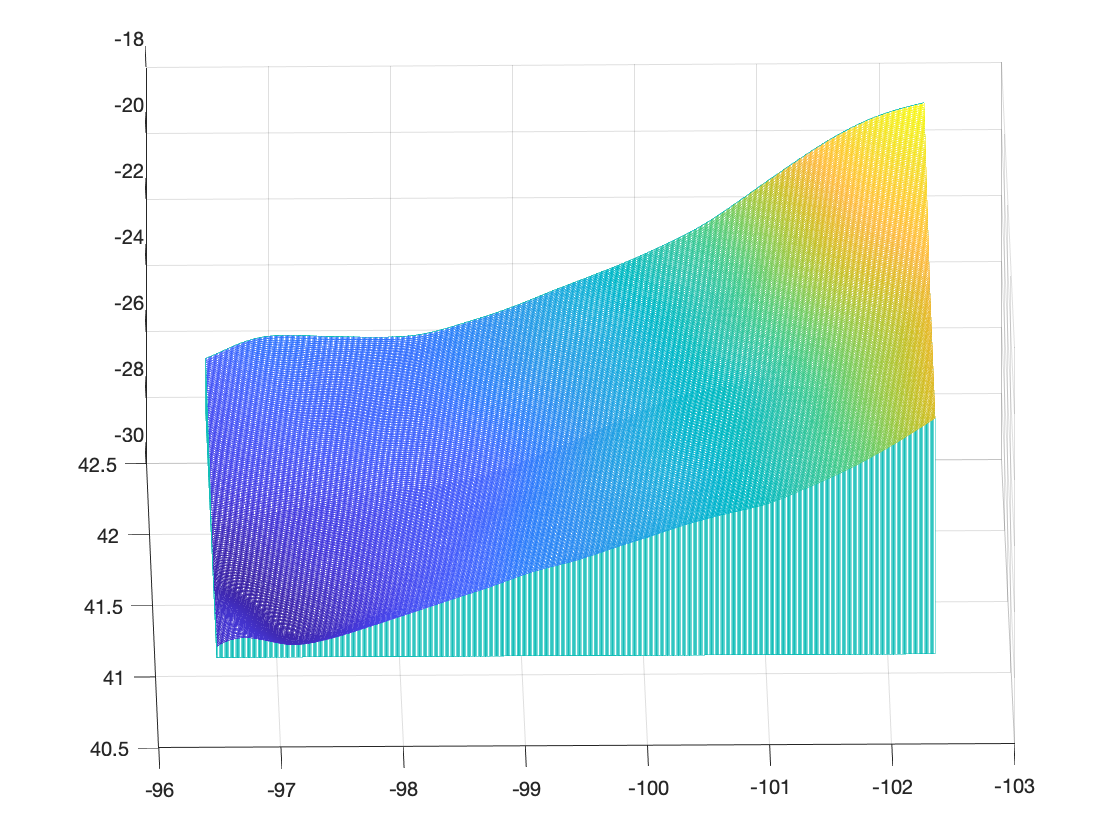

%11
 G = 6.67*10^-6
 rho = 2670
 gamma = calc_gnorm_ellip_surface(Latitude_grid,Ellipsoid);

 
 deltaN_indirect = -(G*rho./gamma).*(pi*Hs.^2 + R^2/6 .* (ifft(fft(Hs.^3).*fft(rq.^3)) - Hs.^3.*ifft(fft(1).*fft(rq.^3))) + 3*R^2/40 .* (ifft(fft(Hs.^5).*fft(rq.^5)) - Hs.^5.*ifft(fft(1).*fft(rq.^5))));
 imagesc(lat,long,deltaN_indirect)
 N_geoid = N_co_geoid+deltaN_indirect

G = 6.6700e-06

 N_ggm = griddata(GGM01C_latitudes,GGM01C_longitudes,GGM01C_geoid,Latitude_grid,Longitude_grid);

rho = 2670

 N_co_geoid = Nr + N_ggm;
 disp('Plotting')
 figure(1)

Unrecognized function or variable 'Hs'.

 clf


help import_airborne_gravity_data


function H1 = addPadding(H)
    sizeH = size(H);
  
    H1 = [H,zeros([sizeH(1) sizeH(2)-1]);zeros([sizeH(1)-1 sizeH(2)]),zeros([sizeH(1)-1 sizeH(2)-1])];
  %   H1 =  [zeroH,zeroH,zeroH;zeroH,H,zeroH;zeroH,zeroH,zeroH];

 
  import_airborne_gravity_data(filepath) imports the observed airborne gravity 
    data (gobserve) of any tile from < https://geodesy.noaa.gov/ GRAV-D/data_products.shtml here >
   
 
  Inputs:
  filepath (string)
 
  Output:
   Matrix with 
    Column 1 - Latitudes  (degrees)  
    Column 2 - Longitudes (degrees)
    Column 3 - gravity (observed) (mgGals)
    Column 4 - ellipsoid height (m)



end
function H1 = addPadding_full(H)
    sizeH = size(H);
    zeroH = zeros(sizeH);
  %  H1 = [H,zeros([sizeH(1) sizeH(2)-1]);zeros([sizeH(1)-1 sizeH(2)]),zeros([sizeH(1)-1 sizeH(2)-1])];
     H1 =  [zeroH,zeroH,zeroH;zeroH,H,zeroH;zeroH,zeroH,zeroH];
end
%----------------------------------------------------------------------------
% get_Ellipsoid(ellipType) returns a structure containing ellipsoid
% parameters for the 'WGS84' and the 'GRS80' ellipsoids.
%
% Input:
% ellipType (string) Accepts 'WGS84' or 'GRS80'
%
% Output: ellipsoid (Struct)
% fields: GM (double) Earth's Gravitational Constant(m^3/s^2)
% omega (double) Angular Velocity of Earth (rad/s)
% gammaEquator (double) Equatorial Normal Gravity (mGal)
% gammaPole (double) Polar Normal Gravity (mGal)
% a (double) Semi-major Axis (m)
% b (double) Semi-minor Axis (m)
% e (double) first eccentricy (unitless)
% e2 (double) first ecentricity squared (unitless)
% f (double) flattening (unitless)

%
function [ellipsoid] = make_Ellipsoid(ellipType)

switch ellipType
 case 'WGS84'
 ellipsoid.GM = 3986004.418E8;
 ellipsoid.omega = 7.292115e-5;
 ellipsoid.gammaEquator = 978032.53359;
 ellipsoid.gammaPole = 983218.49378;
 ellipsoid.a = 6378137.0;
 ellipsoid.b = 6356752.3142;
 ellipsoid.e = 8.1819190842622.*1E-2; %first eccentricity
 ellipsoid.e2 = 6.69437999014.*1E-3; %first eccentricity squared
 ellipsoid.f = 1/298.257223563; %flattening
 %WGS84 defining parameters from NIMA (2004).
 case 'GRS80'
 ellipsoid.GM=3986005E8;
 ellipsoid.omega=7.292115e-5;
 ellipsoid.gammaEquator=978032.67715;
 ellipsoid.gammaPole = 983218.63685;
 ellipsoid.a = 6378137;
 ellipsoid.b = 6356752.3142;
 ellipsoid.e = 0.081819190842622; %first eccentricity
 ellipsoid.e2 = 0.00669437999014; %first eccentricity squared
 ellipsoid.f = 0.00335281066474; %flattening
 %GRS80 defining parameters from Moritz (2000).
 otherwise
 warning('This ellipsoid is not supported')
 return
end
end
%------------------------------------------------------
function gammas = gammas(latitude)
    a = 6378137.0;
    b = 6356752.314140;
    gamma_a = 9.7803267714;
    gamma_b = 9.8321863685;
    omega = 7292115.0*10^11;
    GM = 3986004.418*10^8 ;
    m = ((omega^2)*(a^2)*b)/GM;
    f = (a-b)/a;
    gammas = (a*gamma_a*(cosd(latitude).^2) + b*gamma_b*(sind(latitude).^2))./((a*(cosd(latitude).^2)+b*(sind(latitude).^2)).^0.5);
end